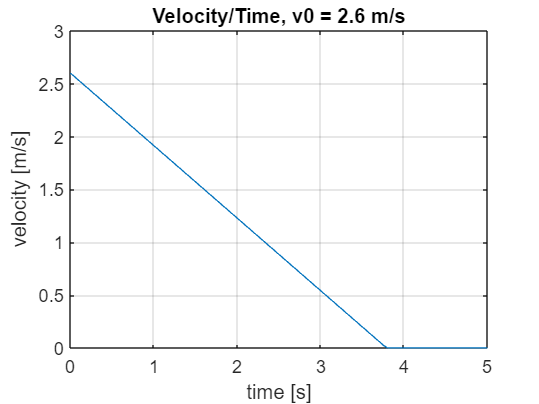

tspan = [0 5];
v0 = 2.6;
[t,y] = odeEuler(@funkODE,tspan,v0,100);

index0 = find(y == 0);
t0 = t(index0(1));
distance = (t0*v0)/2;

if distance < 4
    points = 0;
elseif distance < 4.2
    points = 1;
elseif distance < 4.4
   points = 2;
elseif distance < 4.6
   points = 3;
elseif distance < 4.8
   points = 4;
elseif distance < 5
   points = 5;
else 
    points = 0;
end


plot(t,y)
grid on
xlabel("time [s]")
ylabel("velocity [m/s]")
title("Velocity/Time, v0 = " + v0 + " m/s")

distance

distance = 4.9400

points

points = 5